# Sampled-Data Systems

This livescript is a manual in support of the app ***Continuous_and_Discrete_time_Mapping_control101.mlapp ***and*** Closed_Loop_Under_Sampling_control101.mlapp***.   These are virtual laboratories to help students engage with the concepts of sampling and how that impacts on system behaviour in the open and closed-loop.

Become familiar with impulse transfer functions of sampled-data systems (computer controlled systems) and see its perodicity based on periodicity of frequency spectrum of sampled signals.

$\bullet$ See the perodicity of poles and zeros of impulse transfer function on frequency axis and selection of sampling period considering the this perodicity.

$\bullet$ Visualize pole zero mapping of impulse transfer functions for different sampling periods.

$\bullet$ Learn obtaining discrete-time transfer functions from impulse transfer functions considering z-transform.

$\bullet$ See mapping in between Laplace-plane and z-plane over primary and complemantary strips.

$\bullet$ Perform numerical examples and exercises to see how pole zero distrubition of sampled-data system change for different sampling periods comparing them with pole zero-distribution of corresponding continous time system, and perform further investigation via the  directed App.

For further background on the analysis of sampling see the livescript file: ***Sampling_Operation_control101.mlx, Signal_Types_in_Computer_Controlled_Systems_control101.mlx.***

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%  
%        help control101         (opens within the command window)

Source files created by Mehmet Kilic, Yaprak Yalcin, Istanbul Technical University (İTÜ) and also available separately from [https://drive.mathworks.com/sharing/bf093c57-7f71-4380-bec3-c0fa6ffdb8b9](https://drive.mathworks.com/sharing/bf093c57-7f71-4380-bec3-c0fa6ffdb8b9)

Files edited for inclusion in the toolbox by J.A.Rossiter, University of Sheffield    

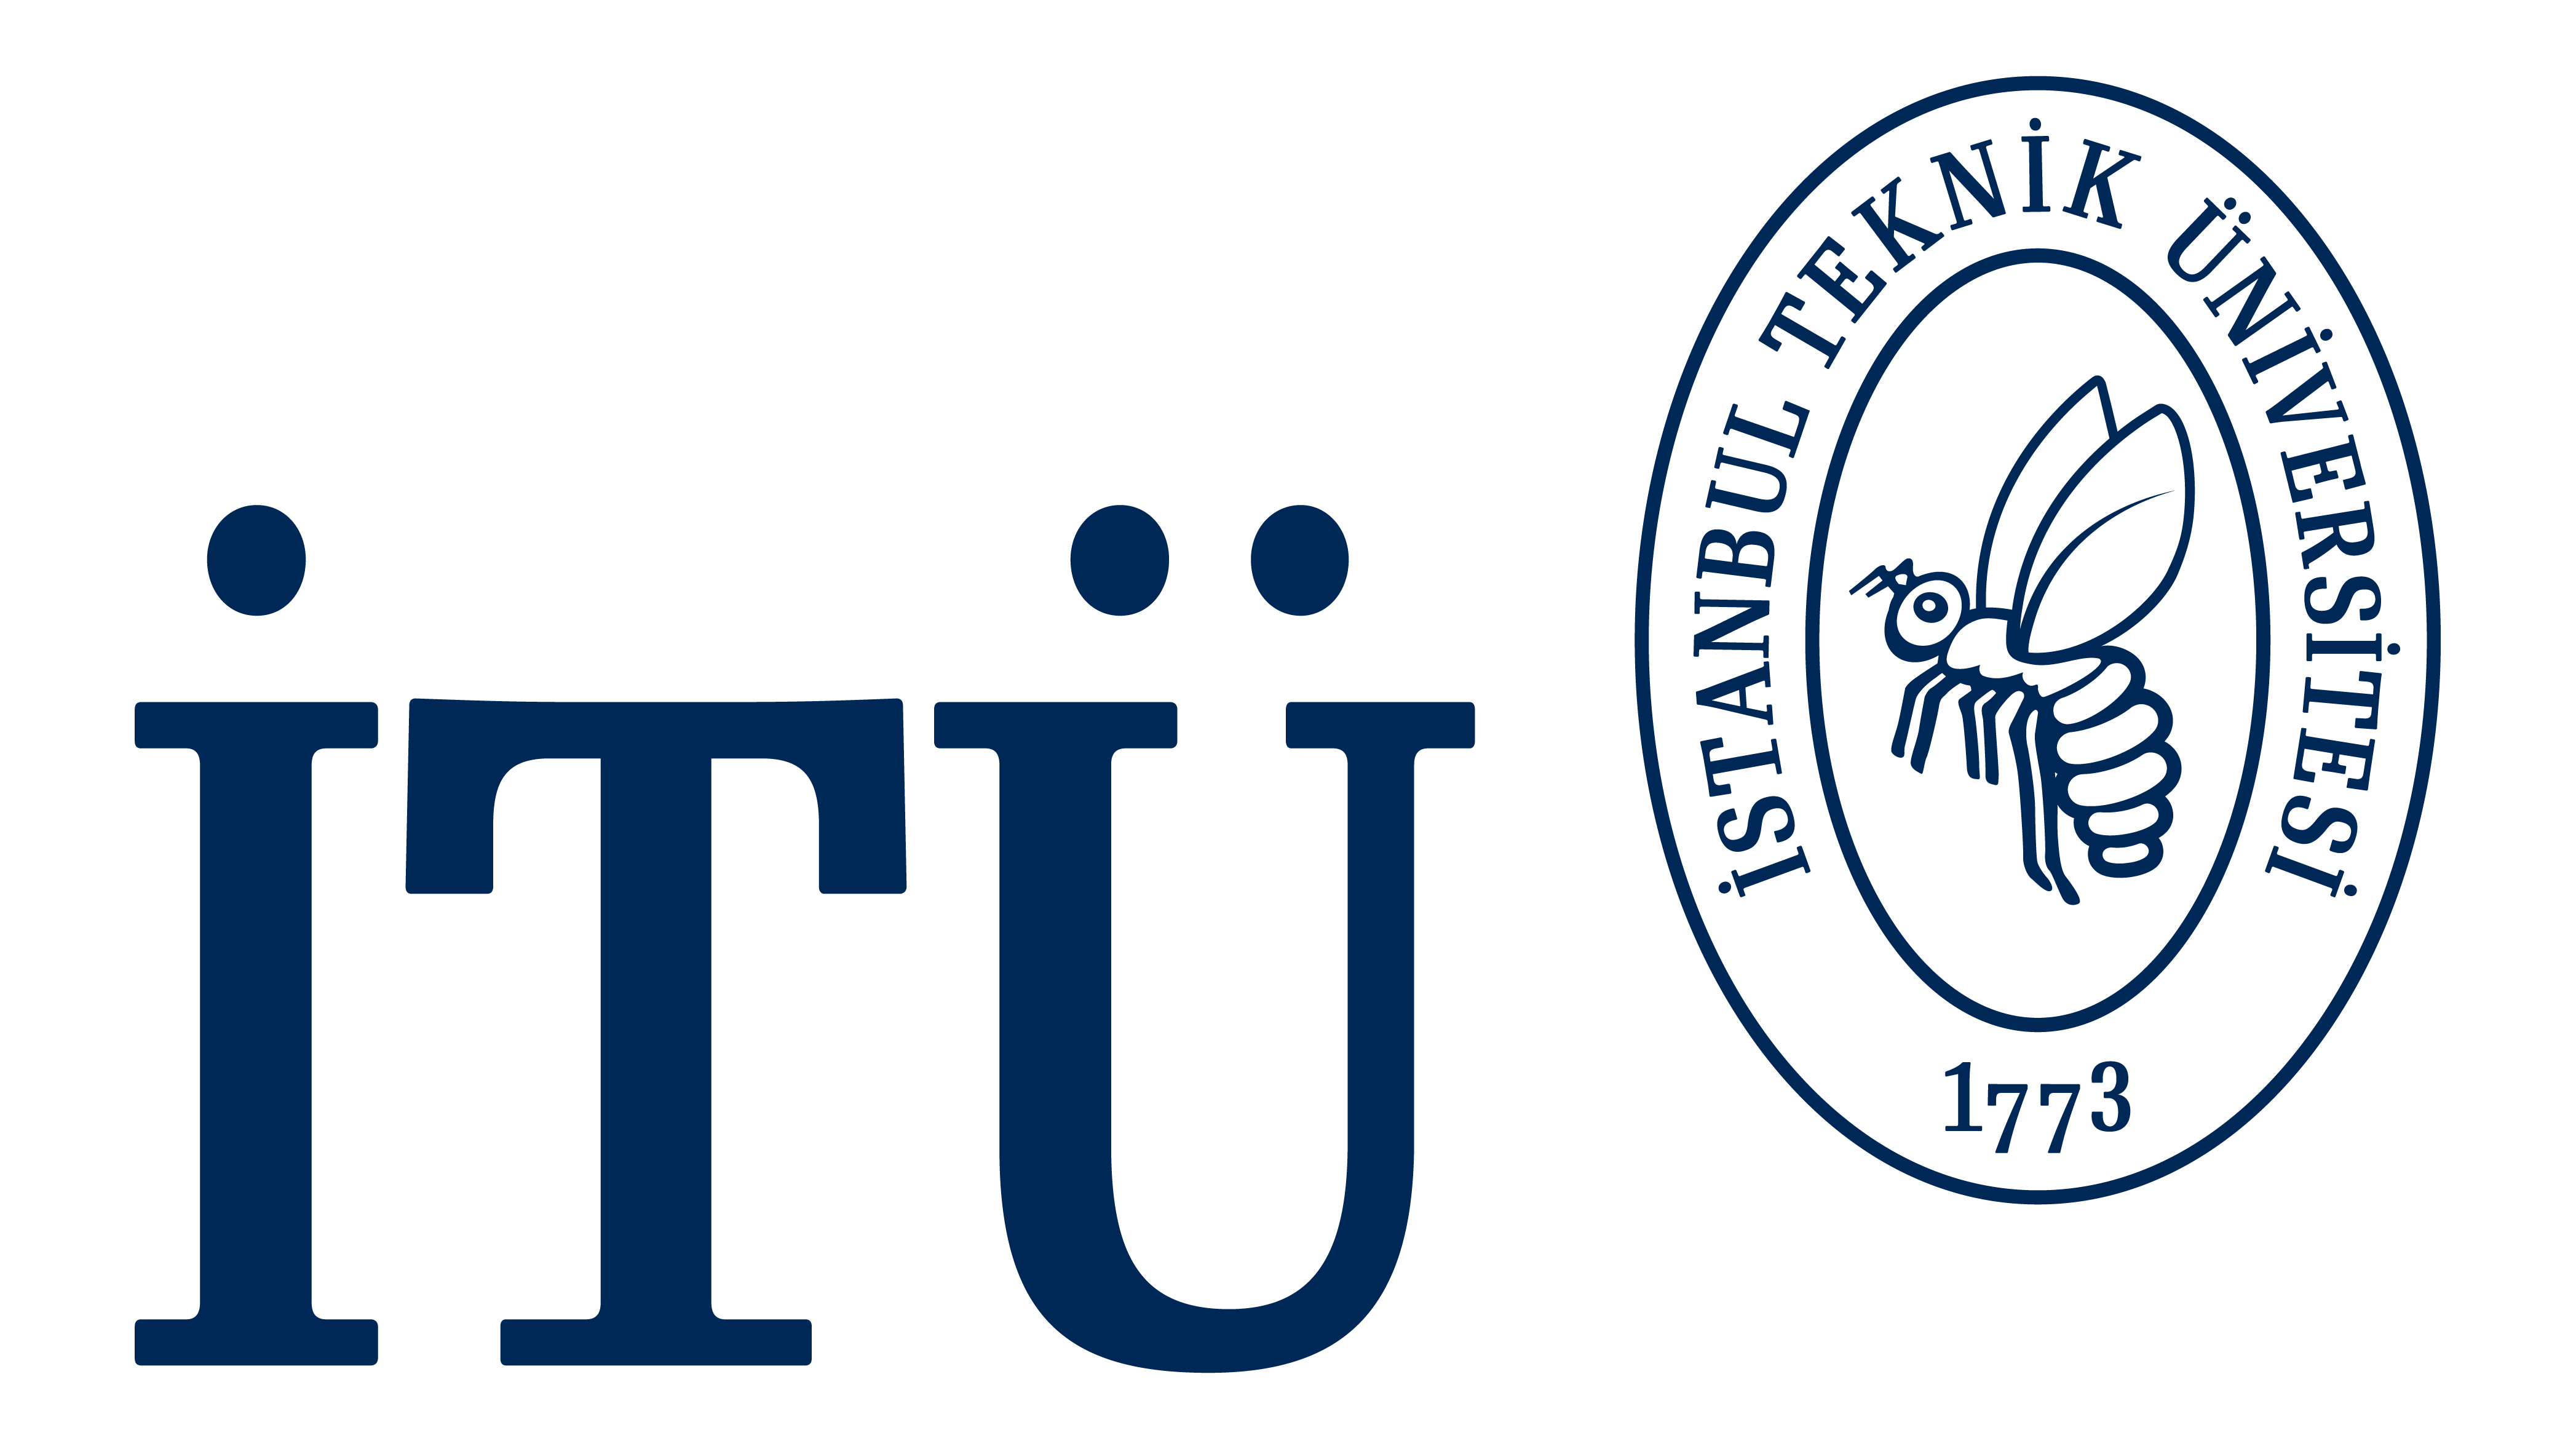                     

## Table of contents

- Introduction to sampling

- Mapping of poles from continuous domain to sampled domain

- The virtual laboratories

## 1 Introduction to sampling

The implementation of control and signal processing inevitably involves computers and thus the data needs to be discretised or sampled for use by the computer. The systems that process sampled-data as seen in Figure 1 are called sampled-data systems. Assuming there exist a sample in the output of the system, the relation between sampled input-signal and output signal can be formulated with impulse transfer functions which is shown in Figure 2.

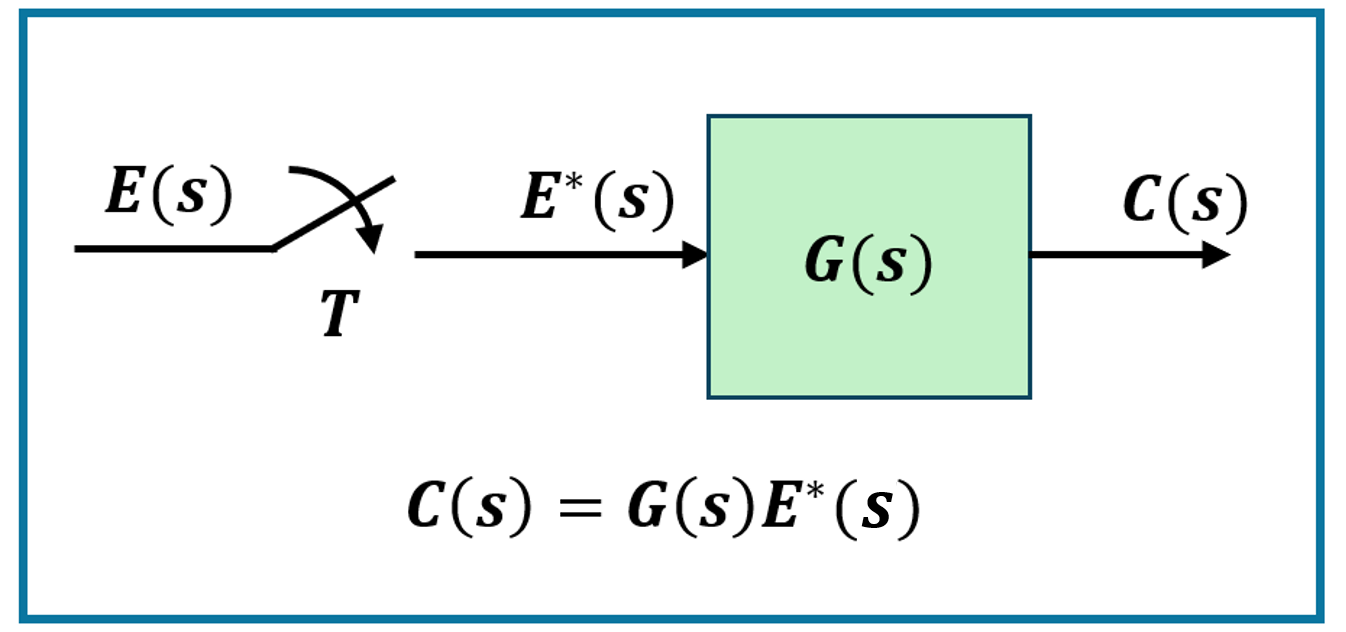

Figure 1. Sampled data-system

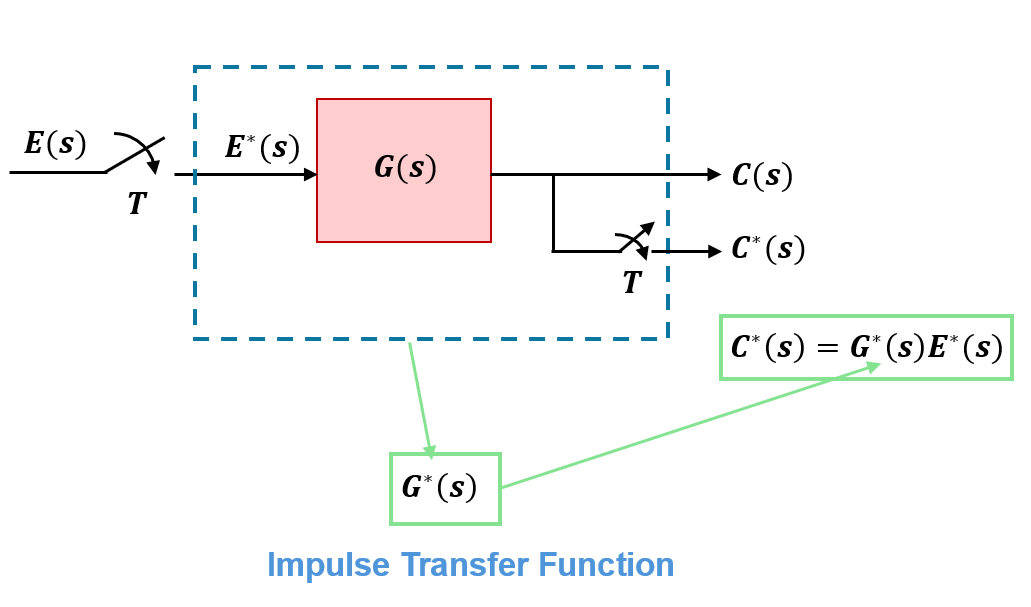

Figure 2. Impulse Tranfer Function

The following notes give a brief summary of some of the background theory before moving onto the use of MATLAB. Students are encouraged to use their course notes and text books for more detail.

### 1.1 The impulse train and sampling

The process of sampling utilises a scaled impulse train. The mathematical expression of an impulse train is:

#### 
$$p\left(t\right)=\sum_{-\infty }^{+\infty } \delta \left(\mathit{\mathbf{t}}-\textrm{kT}\right)$$


The sampled-signal representation in terms of signal values at sampling instances and delta-dirac function (impulse train is modulated with signal values at sampling instances) is:

### $x^* \left(t\right)=\sum_{k=0}^{+\infty } x\left(\textrm{kT}\right)\delta \left(\mathit{\mathbf{t}}-\textrm{kT}\right)$.

The Laplace Transform of sampled-signal based on above expresion is as follows:

### 
$$X^* \left(s\right)=\sum_{k=0}^{+\infty } x\left(\textrm{kT}\right)e^{-\textrm{kTs}}$$


In this Laplace transform, it is common to deploy the following mapping: 

### 
$$z^{-1\;} =e^{-\textrm{sT}}$$


Consequently one can write a transform for the sampled signal (denoted as  the z-transform of sampled-signal).

### 
$$X\left(z\right)=\sum_{k=0}^{+\infty } x\left(\textrm{kT}\right)z^{-k}$$


Therefore, with $z^{-1\;} =e^{-\textrm{sT}}$ , from Impulse transfer function discrete-time transfer function can be directly obtained as seen in Figure  3.

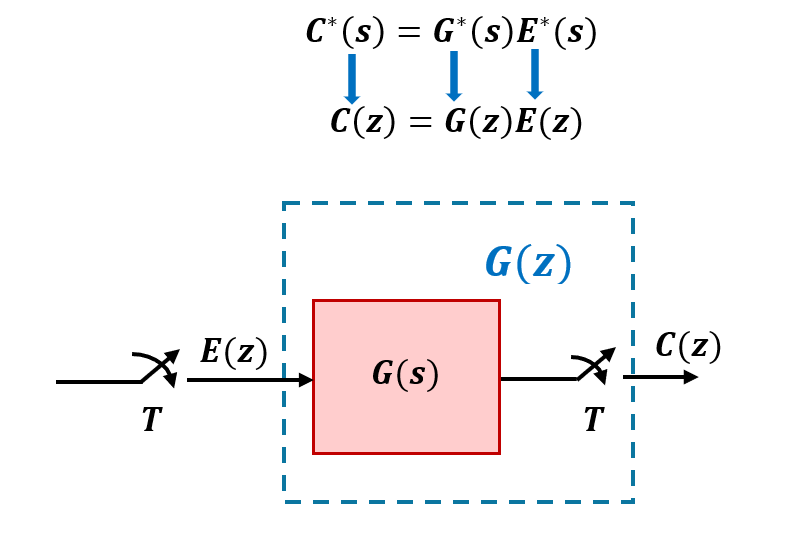

Figure 3: Sampled data system

### 1.2 Background mathematical analysis and aliasing

Based on the frequency response (Fourier Transform) and Laplace tranform of sampled signal are periodic, we can see that the Impulse transfer functions are also periodic. 

Recall the  periodicity of sampled signal $E^* \left(s\right)$.

## 
$$E^* \left(s\right)=\frac{1}{T}\sum_{m=-\infty }^{m=+\infty } E\left(s+\textrm{jm}\omega_s \right)$$


From figure 2, the continous output equation is,

### 
$$C\left(s\right)=G\left(s\right)E^* \left(s\right)$$


and sampled output equation is as follows.

### 
$$C^* \left(s\right)=G^* \left(s\right)E^* \left(s\right)$$


Considering $c^* \left(t\right)$ is a sampled-signal, its Laplace transform $C^* \left(s\right)$ of it can be  writen in terms of C(s) similar to $E^* \left(s\right)$.

### 
$$C^* \left(s\right)=\frac{1}{T}\sum_{m=-\infty }^{m=+\infty } C\left(s+\textrm{jm}\omega_s \right)={\left\lbrack G\left(s\right)E^* \left(s\right)\right\rbrack }^*$$


which yields following equation,

### 
$$C^* \left(s\right)=\frac{1}{T}\sum_{m=-\infty }^{m=+\infty } G\left(s+\textrm{jm}\omega_s \right)E^* \left(s+\textrm{jm}\omega_s \right)$$


Considering perodicity of $E^* \left(s\right)$ as follows,

### 
$$E^* \left(s+\textrm{jm}\omega_s \right)=E^* \left(s\right)$$


The relation between $E^* \left(s\right)$ and $C^* \left(s\right)$can be writen as below.

### 
$$C^* \left(s\right)=E^* \left(s\right)\frac{1}{T}\sum_{m=-\infty }^{m=+\infty } G\left(s+\textrm{jm}\omega_s \right)=G^* \left(s\right)E^* \left(s\right)$$


Therefore,continous transfer-function of sampled-data system, namely impulse transfer function is obtained with following expression with infinite-some of $G\left(s\right)\;$copied at multiples of sampling frequency. It is seen that Impulse transfer function is also periodic.

### 
$$G^* \left(s\right)=\frac{1}{T}\sum_{m=-\infty }^{m=+\infty } G\left(s+\textrm{jm}\omega_s \right)=\frac{1}{T}\lbrace \ldotp \ldotp \ldotp +G\left(s-j\omega_{s\;} \right)+G\left(s\right)+G\left(s+j\omega_{s\;} \right)+\ldotp \ldotp \ldotp \ldotp \rbrace$$


Namely, the poles and zeros of continous-time transfer function G(s) are copied at every multiples of sampling frequency as shown Figure 4. 

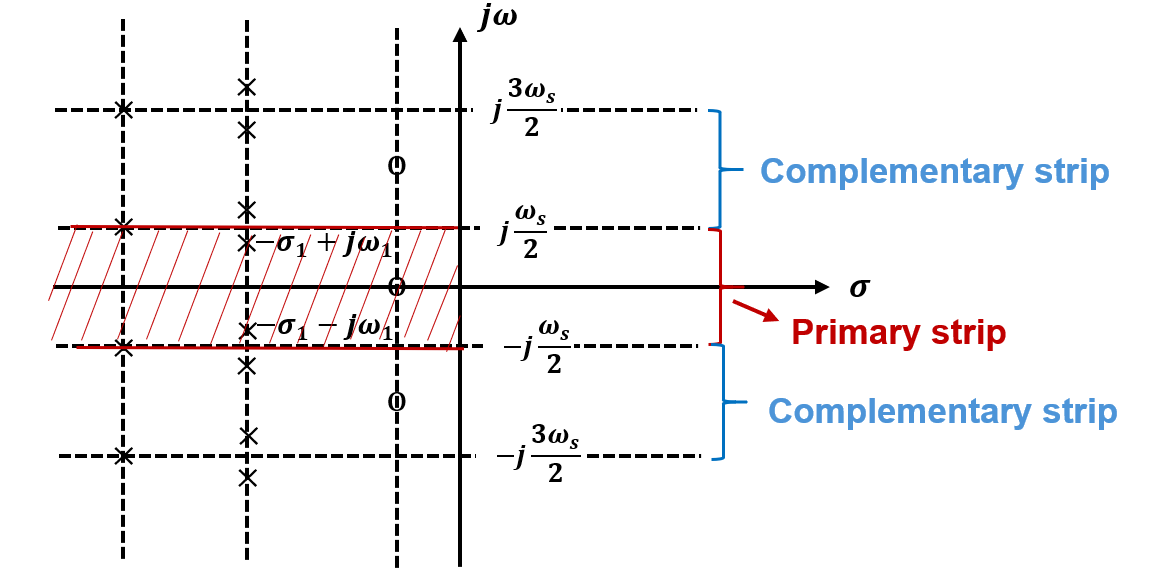

Figure 4. Pole-zero map of Impuse transfer function

In order to avoid aliasing, the sampling period should be selected such that all of the poles of the

- Open Loop System

- Desired Closed Loop system

are INSIDE the Primary Strip.

### 1.3 Example illustrating the repeating poles for a sampled system

The following example plots poles of a continous-time linear system and the corresponding sampled-data system of which the the input and output of the system is sampled with sampling periods of Ts=1s and Ts=10s.

Use the transfer function: $G\left(s\right)=\frac{1}{s^2 +3s+3}$

It should be clear that in the upper figure the open-loop poles (marked with blue crosses) are well within the primary strip whereas with slower sampling, the poles may be outside the primary strip.

G=tf([1],[1 3 3]);
poles_G=pole(G)

poles_G =   -1.5000 + 0.8660i
  -1.5000 - 0.8660i


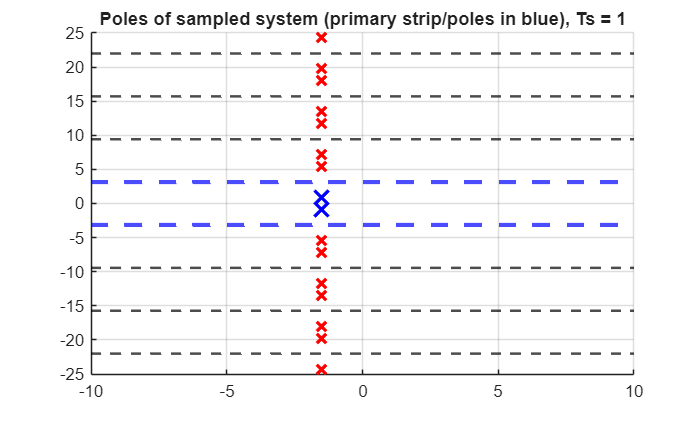

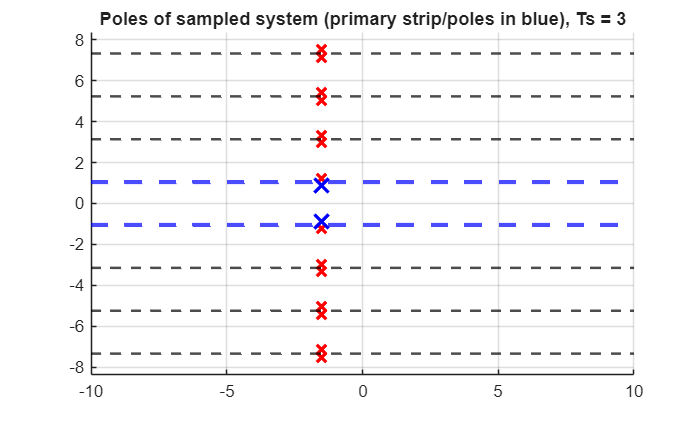

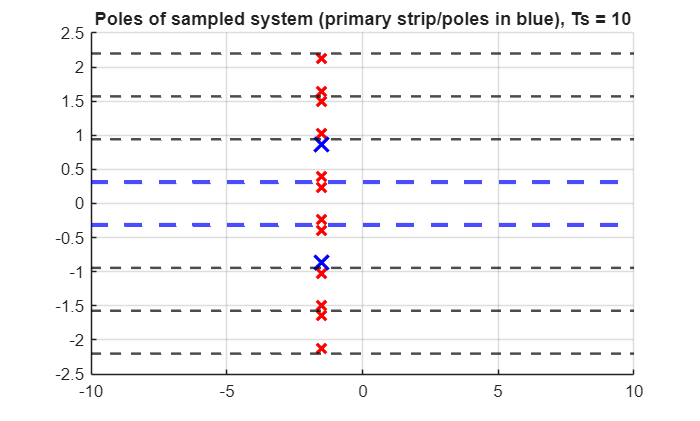


% Do a loop to consider changes in sampling time and sampling frequency
T_values = [1, 3,10];
for i = 1:length(T_values)
    T = T_values(i);
ws = 2*pi/T; 
  % Number of shifts
N = 4; 
figure;hold on;grid on;

% Create a new system to accumulate shifted versions
G_aug = 0;  
s=tf('s');
for n = -N:N
    G_aug =G_aug + 1/((s + 1i*n*ws)^2 + 3*(s + 1i*n*ws) + 3);
end
G_aug=1/T*G_aug;
poles_G_aug=pole(G_aug);
plot(real(poles_G_aug), imag(poles_G_aug), 'rx', 'MarkerSize', 8, 'LineWidth', 2);

%Add dashed horizontal lines at ±(ws/2), ±(3ws/2), etc.
max_order = 2*N-1;  % Decide how many multiples you want to plot
strip_multiples = 3:2:max_order;  % Odd multiples: 1,3,5,...

for k =strip_multiples
    y = k * ws/ 2;
    yline(y, '--k', 'LineWidth', 1.5);    % Positive frequency
    yline(-y, '--k', 'LineWidth', 1.5);   % Negative frequency
end
 yline(ws/2, '--b', 'LineWidth', 2.5);    % Positive frequency
 yline(-ws/2, '--b', 'LineWidth', 2.5);   % Negative frequency

% Add open-loop poles to the plot
plot(real(poles_G), imag(poles_G), 'bx', 'MarkerSize', 12, 'LineWidth', 2);
title(['Poles of sampled system (primary strip/poles in blue), Ts = ', num2str(T)])
xlim([-10;10])
ylim([-N*ws;N*ws])
hold off;

end   % end of loop for different T

### 1.4 Exercise for the student

Consider the second order linear system with transfer function $G\left(s\right)=\frac{s+1}{s^2 +2s+10}$ . Select a sampling period such that there won't be any alisasing in coresponding sampled-data system and plot poles of sampled-data transfer function. 

You can use the same code as in section 1.3 by simply changing the definition of G(s) at the top and the choices of sampling period lower down.

## 2. Mapping of poles from continuous domain to sampled domain

Discretisation uses the basic mapping $z=e^{\textrm{sT}} \;$and thus it is important to understand how equivalent poles appear in the respective domains.

As it is seen in Figure 5, the primary strip in the s-domain is the strip in left half plane in between $-\frac{\omega_s }{2}$ and$\;\frac{\omega_s }{2}$ .  We focus on the LHP for now as that is where stable poles are sited.  This strip is mapped on and inside the unit circle (implicitly poles outside the unit circle are unstable). Note that, complemantary LHP strips are also mapped on and inside the unit circle.

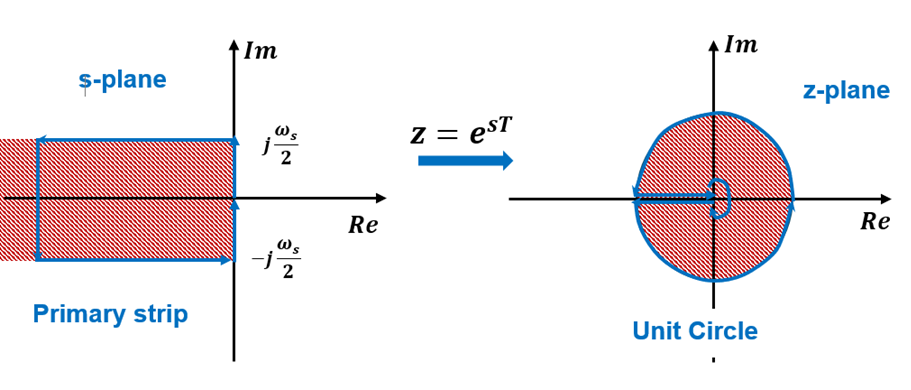

Figure 5. Mapping beween s-plane and z-plane 

In Figure 6, the s-plane to z-plane maping of the points $s=0$, s=$-j\frac{\omega_s }{2}$, $s=j\frac{\omega_s }{2}$, $s=-\infty +j\frac{\omega_s }{2}$ and $s=-\infty -j\frac{\omega_s }{2}$ are illustrated considering $s=\rho +j\omega$ and  $z^{\;} =e^{\textrm{sT}}$. It is easy to determine the mapped z-plane points based on polar coordinate formulation in z-plane $z={\textrm{re}}^{j\theta } =e^{\sigma T} e^{j\omega T}$ where $r$ is the magnitute and $\theta$ is angle of the points.

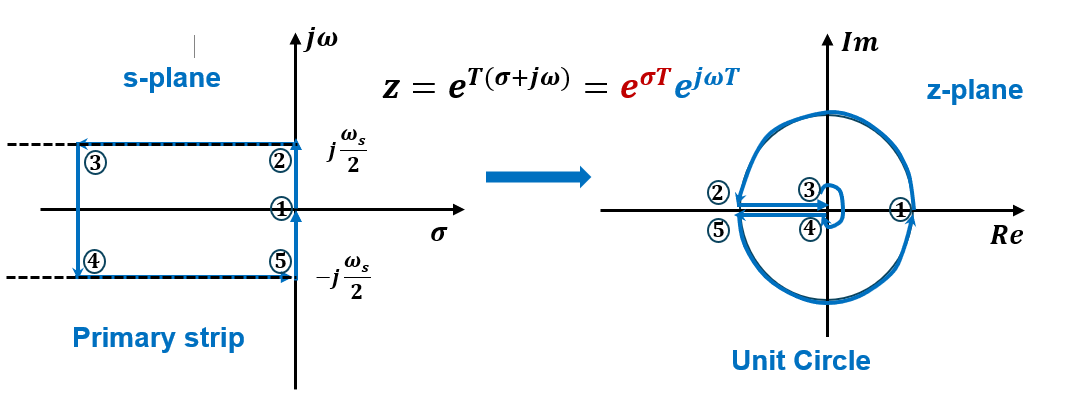

Figure 6. Ilustration of mapping of specific points s-plane based on polar coordinates formulation in z-plane

### 2.1 Illustration of pole mapping 

Following example plots poles of a continous-time system transfer function and discrete-time tranfer function of which the the input and output of the system is sampled with sampling period Ts=0.1, 0.5, 1. You can check how sampling affects  the representation of continous behavior in terms of discrete-time system response.

Consider the continuous system: $G\left(s\right)=\frac{1}{s^2 +3s+3}$. 

- One immediate observation is that the poles move closer to the orgin as the sampling period increases. 

- You may also notice that the phase of the discrete poles increases with sampling period.

disp('***************************************')

***************************************


disp('Section 2 below')

Section 2 below


% Given continuous-time system 
G = tf([1], [1 3 3])


G =
 
        1
  -------------
  s^2 + 3 s + 3
 
Continuous-time transfer function.


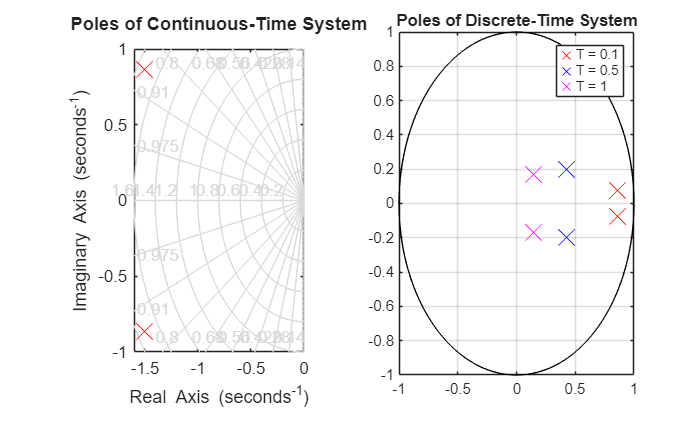

% Discretised system sample rates
T_1 = 0.1;   
T_2= 0.5;  
T_3= 1;
% Discretize system using input and output sampling and with a ZOH
Gz1 = c2d(G, T_1, 'zoh'); 
Gz2 = c2d(G, T_2, 'zoh');
Gz3 = c2d(G, T_3, 'zoh');

% Plot poles of continuous-time system and discrete system
figure; clf
ax=axis();
set(0,'DefaultLineMarkerSize',14);
subplot(121)
pzmap(G,"r");
title('Poles of Continuous-Time System');
grid on;
subplot(122)
p1=pzmap(Gz1); p2=pzmap(Gz2);p3 = pzmap(Gz3);
x=0:.02:2*pi;
plot(real(p1),imag(p1),'rx',real(p2),imag(p2),'bx',real(p3),imag(p3),'mx',cos(x),sin(x),'k');
title('Poles of Discrete-Time System');
grid on;
legend(['T = ',num2str(T_1)],['T = ',num2str(T_2)],['T = ',num2str(T_3)])

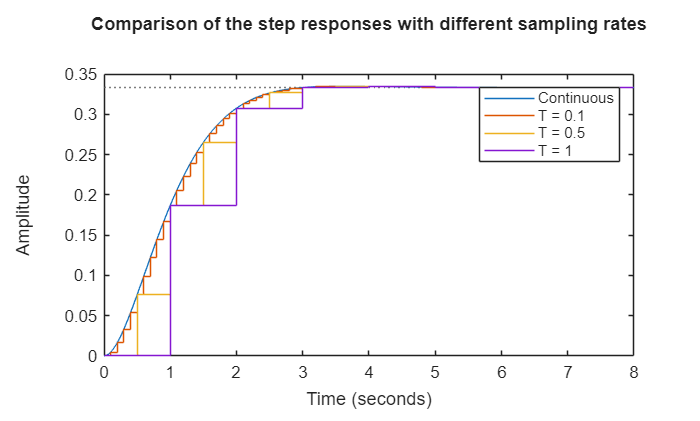


% Step responses
figure
step(G,Gz1,Gz2,Gz3,8)
title('Comparison of the step responses with different sampling rates')
legend('Continuous',['T = ',num2str(T_1)],['T = ',num2str(T_2)],['T = ',num2str(T_3)])

### 2.2 Exercise

Consider the second order linear system with transfer function $G\left(s\right)=\frac{s+1}{s^2 +2s+10}$ . Plot the poles of the continous-time system transfer function and discrete-time tranfer function of which the the input and output of the system is sampled with sampling period Ts=0.1, Ts=1s and T=3s. You can use the code above as a template.

## 3 The virtual laboratories

In order to see the effect of sampling and pole zero map of Benchmark systems in continous-time domain and discrete-time domain refer to the applications named ***Continuous_and_Discrete_time_Mapping_control101.mlapp*** and  ***Closed_Loop_Under_Sampling_control101.mlapp***. These allow users to investigage the impact of sampling and other parameter changes on:

- Behaviours

- Poles

### 3.1 Open-loop behaviours

For open-loop behaviour use the app: ***Continuous_and_Discrete_time_Mapping_control101.mlapp.  ***

This allows users to specify the operating point of a set non-linear system and thus to find a linearised approximation. In addtion the user can specify the sampling time and the input signal type. The choices through sliders and drop downs should be intuitive as seen in Figure 7 below.  The app will automatically overlay each selection so users can investigate the impact of systematic changes, although, due to the number of parameter options available, users will need to keep track themselves of the particular choices made; the app will simply record the simulation 'number' (see bottom left figure).

**WARNING**: The act of changing the sample rate makes the input signal 'appear to change'. In fact it has not changed, it is merely that the changes in value are only noted at the sample instants which will not overlap for different sample rates.

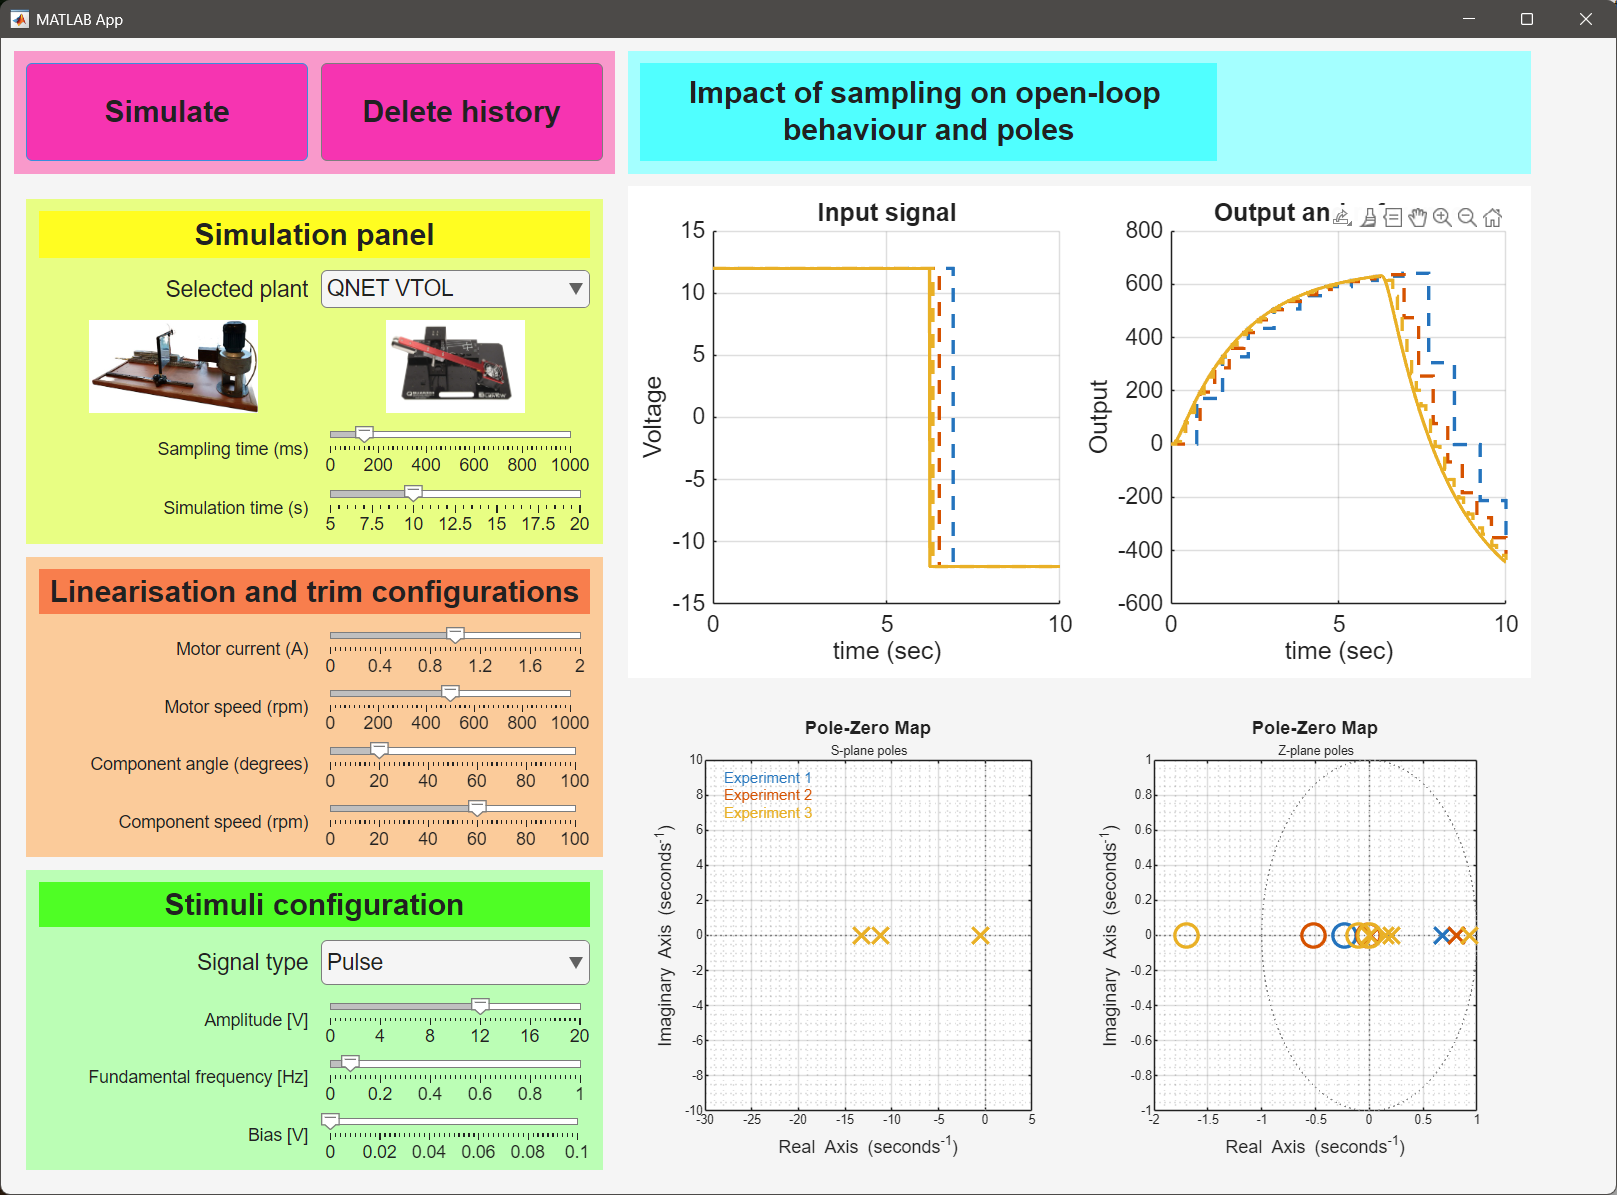

Figure 7: The ***Continuous_and_Discrete_time_Mapping_control101.mlapp ***interface.

### 3.2 Closed-loop behaviours

For closed-loop behaviour use the app: ***Closed_Loop_Under_Sampling_control101.mlapp.  ***

This has similar functionality to the open-loop app, but in addtion allows the user to select two more core options:

- Proportional feedback is assumed. The user can select the value of this and thus investigage the impact of different proprotional gain values.

- The discrete to continuous operation allows  tow alternatives, either a zero or first order hold.

The choices through sliders and drop downs should be intuitive as seen in Figure 8 below.  Obvious investigations that the user may like to consider are:

- Systematic changes to only sampling rate and the impact on the closed-loop poles.

- The impact of changes in proportional gain.

- Impact of changing the hold mechanism.

The app will automatically overlay each selection so users can investigate the impact of systematic changes, although, due to the number of parameter options available, users will need to keep track themselves of the particular choices made; the app will simply record the simulation 'number' (see bottom left figure).

## 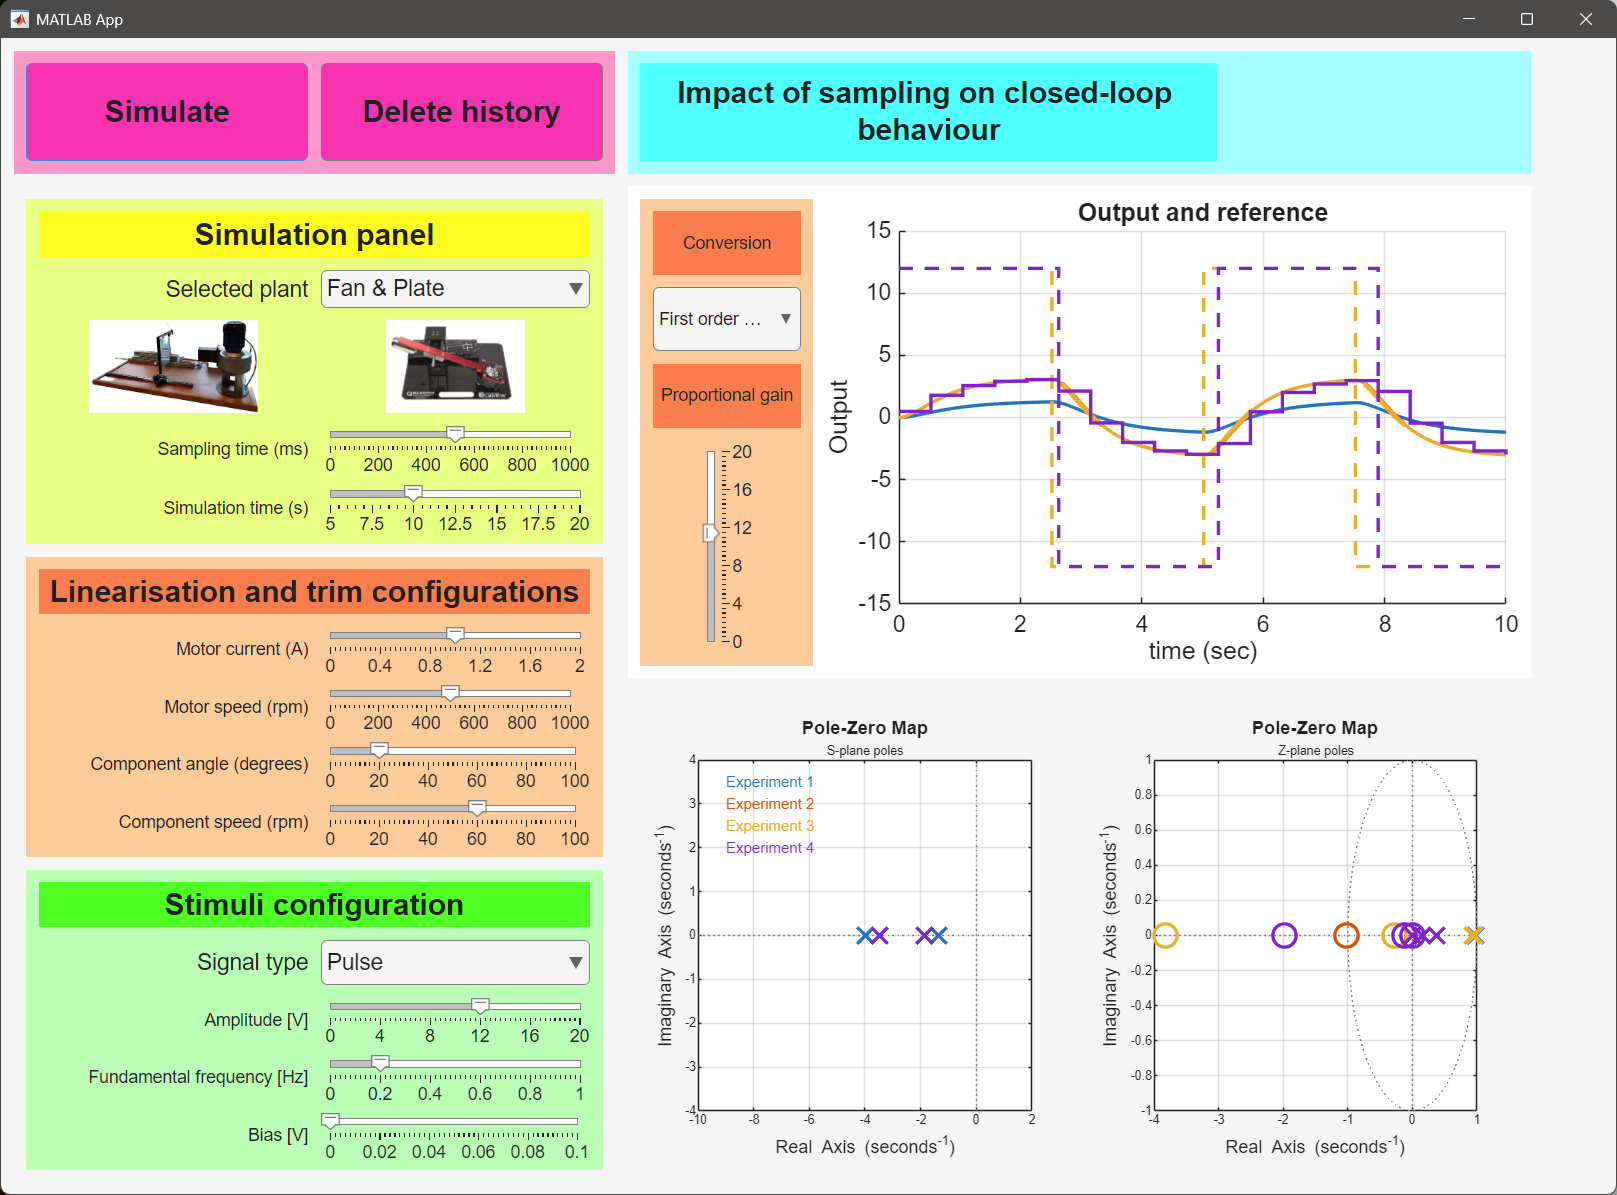

Figure 8: The ***Closed_Loop_Under_Sampling_control101.mlapp ***interface.